# 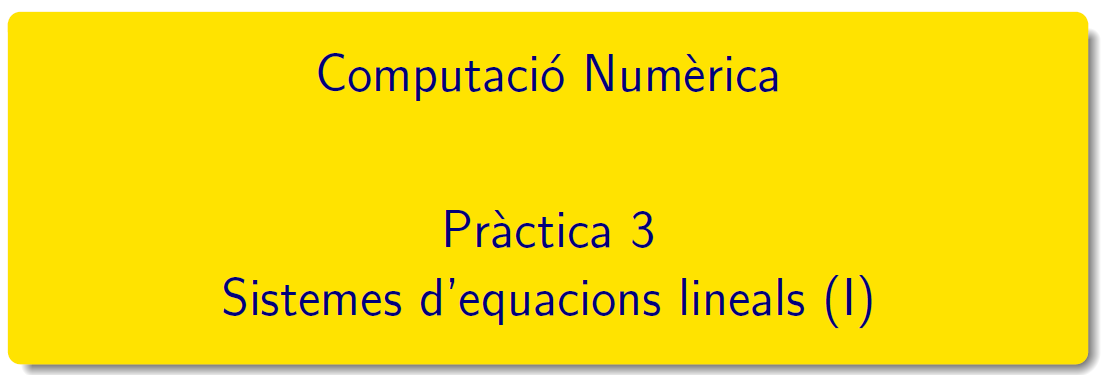

=======================================================================================

# Pràctica 3 - Primera part

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document  CN-tema2-QT2223.pdf que podeu trobar en el campus virtual. 

[Matrius de Matlab](https://es.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html) (resum de com treballar amb matrius) Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

#### **Exercici 1**. Àlgebra lineal

Calculeu  el determinant, la transposta, la inversa, els valors propis i els vectors propis de la matriu A definida per


$$A=\left(\begin{array}{rrr} 1 & 2 & 1\\ -2 & 7 & 3\\ 1 &-1 &10 \end{array}\right)$$


A=[1 2 1; -2 7 3; 1 -1 10]
det(A),A',iA=inv(A)
[V,D]=eig(-A)
rho = abs(eigs(-A,1))       %%%  rho(A) <||A||

#### **Exercici 2**. Regla de Cramer

Escriu un script  i resol el sistema lineal següent fent ús de la regal de Cramer


$$\begin{array}{lcc}
		2x_1+4x_2+x_3 & = & 1\,,\\
		8x_1-x_2+3x_3 & = & 0\,,\\
		2x_1+5x_2 & = & 0\,.\\
	\end{array}$$


A=[2,4,1; 8,-1,3; 2,5 0]   %  matriu coeficients
b=[1;0;0]                  %  vector terme independent
d=det(A)                   % determinant de la matriu

Primera variable

A1=A; A1(:,1)=b, d1=det(A1), x1=d1/d

Segona variable

A2=A; A2(:,2)=b, d2=det(A2), x2=d2/d

Tercera variable

A3=A; A3(:,3)=b, d3=det(A3); x3=d3/d

Solució numèrica de Matlab 

x=linsolve(A,b)

### Mètodes directes

Documentació de Matlab: [Sistemas lineales](https://es.mathworks.com/help/matlab/math/systems-of-linear-equations.html) - [Systems of linear equations](https://es.mathworks.com/help/matlab/math/systems-of-linear-equations.html?lang=en)

MATLAB implementa mètodes directes a través dels operadors de divisió de matrius [`/`](https://es.mathworks.com/help/matlab/ref/mrdivide.html) i [`\`](https://es.mathworks.com/help/matlab/ref/mldivide.html), així com funcions com [`decomposition`](https://es.mathworks.com/help/matlab/ref/decomposition.html), [`lsqminnorm`](https://es.mathworks.com/help/matlab/ref/lsqminnorm.html), and [`linsolve`](https://es.mathworks.com/help/matlab/ref/linsolve.html).

#### **Exercici 3**. Matriu mal condicionada

Verifiqueu si un petit canvi a la matriu de coeficients del sistema lineal incueix grans canvis en la solució per als sistemes d'equaions següents


$$a) \left\{\begin{array}{rcrcr}7x&+&2y&=&6 \\ x&+&0.28y&=&2 \\ \end{array}\right. 
		\qquad	
		b) \left\{\begin{array}{rcrcr}7x&+&2y&=&6 \\ x&+&0.285y&=&2 \\ \end{array}\right.$$


A=[7 2;1 0.28];b=[6;2];x=A\b
A2=[7 2;1 0.285];b=[6;2];x2=A2\b
ec=abs(x-x2)
dx = norm(x-x2,'inf'), erx=dx/norm(x,'inf')
eA = abs(A-A2)
dA = norm(A-A2,'inf'),erA=dA/norm(A,'inf') 
det(A),det(A2)
fita = cond(A,'inf')

#### Exercici 4.  Matrius i vectors predefinits en MATLAB®

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$   

- Amb zeros a  totes les seves components

- Amb uns a les seves components

- Amb nombres al·leatòris uniformes de l'interval [-2,2]

- Amb nombres al·leatòris normals amb $\mu = 0$ i $\sigma = 1$

#### Exercici 5.  Sistemes triangulars superiors

Genereu un script en Matlab per trobar la solució d'un sistema lineal triangular superior pel mètode de substiució enrera. 

% funció del llibre NCM de Moler

**JOC DE PROVES**

Resoleu els següents sistemes lineals:


$${\text a)}\ \left\{\begin{array}{rcr}
	3x-2y+z-t&=&8 \\ 4y-z+2t&=&-3\\ 2z+3t&=&11\\5t&=&15\end{array}\right.$$


U = [3 -2 1 -1; 0 4 -1 2; 0 0 2 3; 0 0 0 5 ]
b = [8 -3 11 15]'
x = backsubs(U,b)

b)  Definiu la matriu  $U=\left(u_{ij}\right)_{15\times 15}$ i el vector  $b=(b_{i})_{15\times 1}$ com  $u_{ij}=\left\{\begin{array}{rr} \cos (ij) & i\leq j\,,\\ & \\ 0 & i>j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=\tan (i)$

#### Exercici 6.  Sistemes triangulars inferiors

Genereu un script en Matlab per trobar la solució d'un sistema lineal triangular inferior pel mètode de substiució endavant. 

% funció del llibre NCM de Moler

**JOC DE PROVES**

Resoleu els següents sistemes lineals:


$${\text c)}\ \left\{\begin{array}{lcr}
	5x&=&-10 \\ x+3y&=&4\\ 3x+4y+2z&=&2\\-x+3y-6z-t&=&5\end{array}\right.$$


L = [5 0 0 0; 1 3 0 0; 3 4 2 0; -1 3 -6 -1]
b = [-10;4; 2; 5]
x = forward(L,b)

d) Definiu la matriu  $l=\left(l_{ij}\right)_{20\times 20}$ i el vector  $b=(b_{i})_{20\times 1}$ com  $l_{ij}=\left\{\begin{array}{rr} i+j & i\geq j\,,\\ & \\ 0 & i<j\,, \end{array}\right.
\qquad\mbox{i}\qquad b_{i1}=i\,.$

#### Exercici 7.  Eliminació gaussiana

Genereu un script de Matlab per trobar la solució d'un sistema lineal Ax=b pel mètodes d'eliminació gaussiana

** JOC DE PROVES**


$$e)\quad  A=\left (\begin{array}{rrrr}
		10 & -7 & 0 &  1\\
		-3 &  2 & 6 &  0\\
		5 & -1 & 5 &  0\\
		-1 &  0 & 2 & -1
		\end{array} \right)\quad\quad
	b=\left( \begin{array}{r} 7\\4\\6\\-3\end{array} \right).$$



$$f) \quad A=\left (\begin{array}{rrrr}
		 6 & -2  & 2 & 4\\
		12 & -4  & 2 & 2\\
		 3 & -13 & 9 & 3\\
		-6 &  4 & 1 & -18
	\end{array} \right)\quad\quad
	b=\left( \begin{array}{r} 12\\34\\27\\-38\end{array} \right).$$


AM=[6 -2 2 4 12; 12 -4 2 2 34; 3 -13 9 3 27; -6 4 1 -18 -38];
[~,U]=lugui(AM) 

x = backsubs(U(1:4,1:4),U(:,5))
% AM(1:4,1:4)\AM(:,5)

g) Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$ com  $a_{ij}=\left\{\begin{array}{rl} (-1)^{i} &\ i=j\,,\\ & \\ 2 &\ 1\le|i-j|\le 2\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=i\,.$

### Mètodes compactes

#### Factoritzacions en Matlab®

Consulteu [LU, Txoleski i QR](https://es.mathworks.com/help/matlab/math/factorizations.html)

#### Exercici 8. Descomposició LU

Trobeu la descomposició LU de la matriu del sistema d'equacions lineals A i després resoleu el sistema d'equacions lineals Ax=b.


$$a) \qquad (A\,\vert\,b)=\left (
	\begin{array}{rrr|r}
		1 & 6 & 0\  & \ 3\\
		2 & 1 & 0\  & \ 1\\
		0 & 2 & 1\  & \ 1
	\end{array}\right )$$



$$b)\quad	(A\,\vert\,b)=\left ( \begin{array}{rrrr|r}
		6 & -2 & 2 & 4\ &\  0\\
		12& -8 & 4 & 10\  &\  -10\\
		3 & -13 & 3 & 3\  &\  -39\\
		-6 & 4 & 2 & -18\  &\  -16
	\end{array}\right ),$$


A=[6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]
[L,U,P]=lu(A)
b=[0 -10 -39 -16]'
% primer pas
y = forward(L,P*b)
% segon pas
x = backsubs(U,y)
U\(L\P*b)

   
$$c)\quad \left\{ \begin{array}{rcrcrcrcr}
	6x_1 &+& 2x_2 &-& x_3&-& x_4&=&0\\
	2x_1 &+& 4x_2 &+& x_3& & &=&7\\
	-x_1 &+& x_2 &+& 4x_3 &-& x_4 &=&-1\\
	-x_1 & & &-& x_3&+&3x_4&=&-2
	\end{array}\right.$$


#### Exercici 9. Inversa d'una matriu a partir de la descomposició LU


$$	a)\quad  A=\left ( \begin{array}{rrrr}
	6 & 2 & 1 & -1 \\
	2 & 4 & 1 & 0 \\
	1 & 1 & 4 & -1 \\
	-1 & 0 & -1 & 3
	\end{array}\right )$$$$


A = [6 2 1 -1; 2 4 1 0; 1 1 4 -1; -1 0 -1 3]
[L,U,P]=lu(A)

Primera columna 

B=eye(size(A));
b = B(:,1);
x1 = U\(L\P*b)

Segona columna

b = B(:,2);
x2 = U\(L\P*b)

Tercera columna

b = B(:,3);
x3 = U\(L\P*b)

Quarta columna

b = B(:,4);
x4 = U\(L\P*b)

Control/verificació

iA=[x1,x2,x3,x4]
format default
% A*iA, iA*A
U\(L\P*B)


$$b)\quad A=\left(\begin{array}{cccc}
		1&2&3&4\\1&4&9&16\\1&8&27&64\\1&16&81&216\end{array}\right)$$


#### Exercici 10. Mètode QR

Trobeu la descomposició QR de la matriu del sistema d'equacions lineals A i després resoleu el sistema d'equacions lineals AX=b següents


$$a)\ \left\{ \begin{array}{rcr}
			6x_1 + 2x_2 - x_3 - x_4&=&0\\
			2x_1 + 4x_2 + x_3 &=&7\\
			-x_1 + x_2 + 4x_3 - x_4 &=&-1\\
			-x_1 - x_3+3x_4&=&-2
		\end{array}\right.$$



$$b)\ \left\{ \begin{array}{rcr}
			0.05x_1+0.07x_2+0.06x_3+0.05x_4&=&0.23\\
			0.07x_1+0.10x_2+0.08x_3+0.07x_4&=&0.32\\
			0.06x_1+0.08x_2+0.10x_3+0.09x_4&=&0.33\\
			0.05x_1+0.07x_2+0.09x_3+0.10x_4&=&0.31
			\end{array}\right.$$


function x = forward(L,x)
% FORWARD. Forward elimination.
% For lower triangular L, x = forward(L,b) solves L*x = b.
[n,n] = size(L);
    for k = 1:n
        j = 1:k-1;
        x(k) = (x(k) - L(k,j)*x(j))/L(k,k);
        end
end
function x = backsubs(U,x)
% BACKSUBS. Back substitution.
% For upper triangular U, x = backsubs(U,b) solves U*x = b.
[n,n] = size(U);
    for k = n:-1:1
        j = k+1:n;
        x(k) = (x(k) - U(k,j)*x(j))/U(k,k);
    end
end

`Document preparat per M. Àngela Grau Gotés 1 de març de 2023`